**Properties of derivative filters**

First order derivative filter

fs = 128;   %Assume fs as 128HZ
T = 1/fs;  

f_numerator = (1/T)*[1,-1];
f_denominator = 1;

fvtool(f_numerator, f_denominator,'polezero');
fvtool(f_numerator, f_denominator, 'FrequencyScale', 'linear');
fvtool(f_numerator, f_denominator, 'FrequencyScale', 'log');

[H, w] = freqz(f_numerator, f_denominator);

magnitude_response = abs(H);
max_magnitude = max(magnitude_response);
G = 1/max_magnitude;
% max_frequency = w(find(magnitude_response == max_magnitude, 1))

fvtool(G*f_numerator,f_denominator,'FrequencyScale', 'linear');

Second order derivative filter

s_numerator = (1/T)*[1,0,-1];
s_denominator = 1;

fvtool(s_numerator, s_denominator,'polezero');
fvtool(s_numerator, s_denominator, 'FrequencyScale', 'linear');
fvtool(s_numerator, s_denominator, 'FrequencyScale', 'log');

[H, w] = freqz(s_numerator, s_denominator);

magnitude_response = abs(H);
max_magnitude = max(magnitude_response);
G = 1/max_magnitude;
% max_frequency = w(find(magnitude_response == max_magnitude, 1))

fvtool(G*s_numerator,s_denominator,'FrequencyScale', 'linear');

**FIR derivative filter application**

clear;
clc;
load ("ECG_rec.mat");

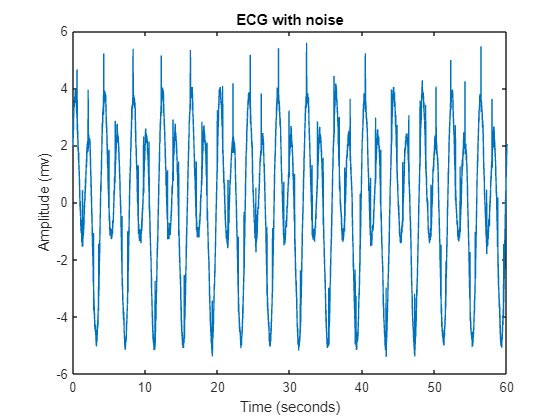

fs = 128;  
T = 1/fs;  

num_points = size(ECG_rec, 2);
time_axis = linspace(0, T * (num_points-1), num_points);  %time axis from the frequency

Snr = 10; 
seed = 10;
nECG = awgn(ECG_rec,Snr,'measured',seed);

EMG_t = 2*sin(2*(pi/4)*time_axis) + 3*sin(2*(pi/2)*time_axis+pi/4);
nECG = nECG + EMG_t;

figure;
plot(time_axis, nECG);
xlabel('Time (seconds)');
ylabel('Amplitude (mv)');
title('ECG with noise');

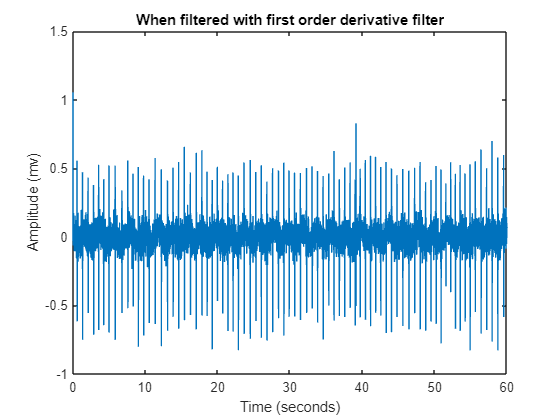

f_numerator = (1/T)*[1,-1];
f_denominator = 1;

[H, w] = freqz(f_numerator, f_denominator);
f_magnitude_response = abs(H);
f_max_magnitude = max(f_magnitude_response);
G_f = 1/f_max_magnitude;

first_order_output = filter(G_f*f_numerator,f_denominator,nECG);

figure;
plot(time_axis,first_order_output);
xlabel("Time (seconds)");
ylabel("Amplitude (mv)");
title("When filtered with first order derivative filter");

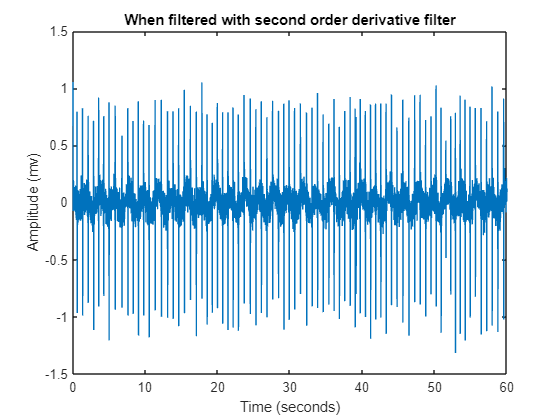

s_numerator = (1/T)*[1,0,-1];
s_denominator = 1;

[H, w] = freqz(s_numerator, s_denominator);
s_magnitude_response = abs(H);
s_max_magnitude = max(s_magnitude_response);
G_s = 1/s_max_magnitude;

second_order_output = filter(G_s*s_numerator,s_denominator,nECG);

figure;
plot(time_axis,second_order_output);
xlabel("Time (seconds)");
ylabel("Amplitude (mv)");
title("When filtered with second order derivative filter");